# Eksamensæt

**M3NUM1 Anvendte Numeriske Metoder -- 16-01-2023**

**Mathias Bruun Houmøller -- 202006837 -- Au666097**

## Opgave 1

clear
format short %formater resultater til 4 decimaler
u = symunit; %Laver symbolske si enheder
% separateUnits(x)
% unitConvert(expr,units)

### (1a)

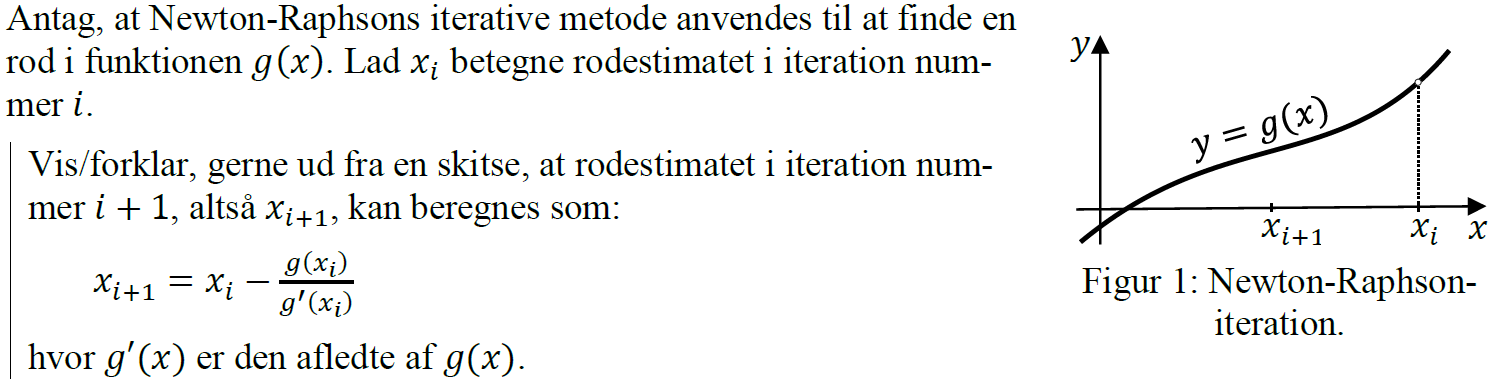

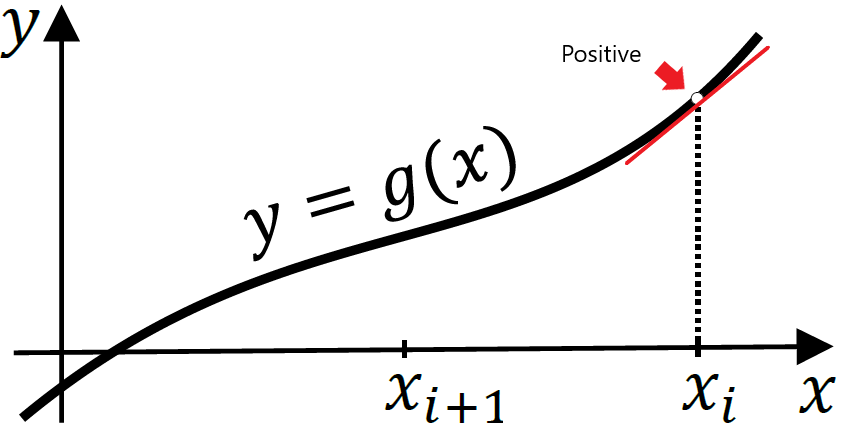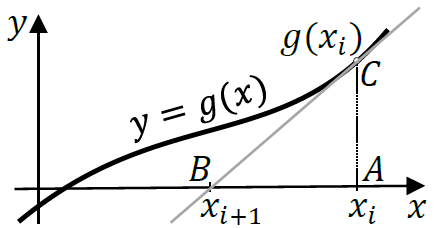

Vi ser at hældnings koeficienten $g'(x)$ er positiv i $x_i$ dermed får vi at $x_{i+1}<x_i$ da $-\frac{g(x)}{g'(x)}$ er negativ. flytnings afstanden i den negative retning bliver forholdet imellem funktionsværdien og den afledte.

Der laves således også en trekant ud af hældningen (ABC) da vi har $g'(x) = \frac{g(x)}{x_i -x_{i+1}}$ hvor vi ser at


$$g(x) = C \\ x_i = A \\ x_{i+1} = B$$


og dermed ses den flytning der sker i negativ retning.

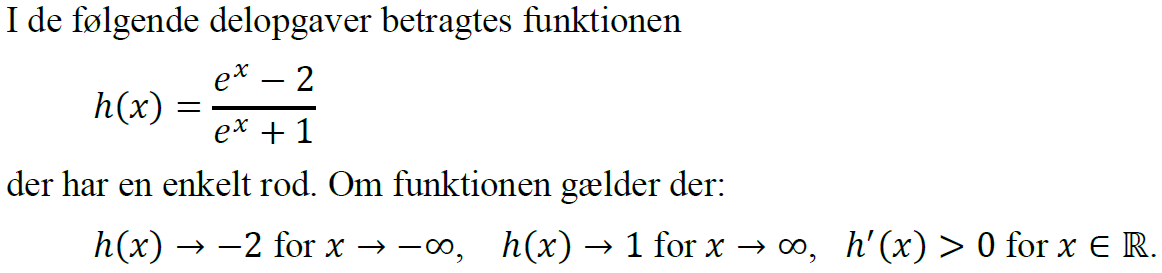

### (1b)

Plot funktionen i intervallet fra 𝑥=−5 til 5 ved brug af MATLAB, og bestem den omtrentlige værdi af roden ud fra plottet. Besvarelsen skal indeholde anvendt MATLAB-kode samt plottet og den aflæste rod med én decimal.

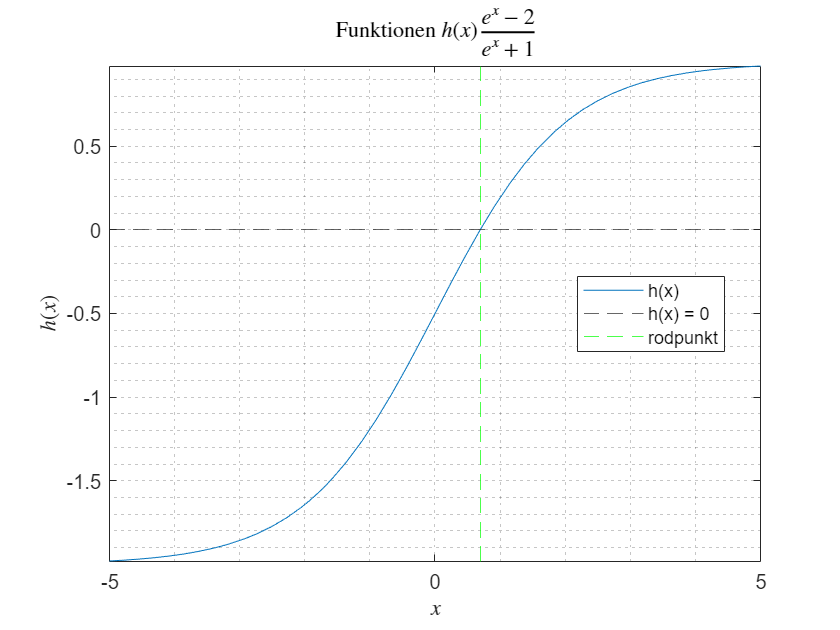

syms x
h(x) = (exp(x) - 2) / (exp(x) + 1);
fplot(h(x), [-5,5], 'DisplayName', 'h(x)')
%der plottes
hold on
yline(0,'--', 'DisplayName', 'h(x) = 0')
xline(0.7,'g--', 'DisplayName', 'rodpunkt')
% formalier
legend('location', 'best')
title('Funktionen $h(x) \frac{e^x - 2}{e^x + 1}$', 'interpreter', 'latex')
xlabel('$x$', 'interpreter', 'latex')
ylabel('$h(x)$', 'interpreter', 'latex')
grid('minor')
hold off

**Rodden findes i punktet med x-værdien 0,7.**

### (1c)

Anvend Newton-Raphsons metode med et startgæt på 𝑥0=2,5 til at bestemme en rod i funktio-nen ℎ(𝑥). Gennemfør 5 iterationer. Besvarelsen skal indeholde beregningsresultater og bereg-ningsformler for de enkelte iterationer (på tabelform vha. fx Excel). Anfør som facit den fundne rod med sikre decimaler (efter afrunding).

h_1(x) = diff(h(x), x)

$$h\_1(x) = \frac{{\mathrm{e}}^{x}}{{\mathrm{e}}^{x}+1}-\frac{{\mathrm{e}}^{x}\,\left({\mathrm{e}}^{x}-2\right)}{{\left({\mathrm{e}}^{x}+1\right)}^{2}}$$

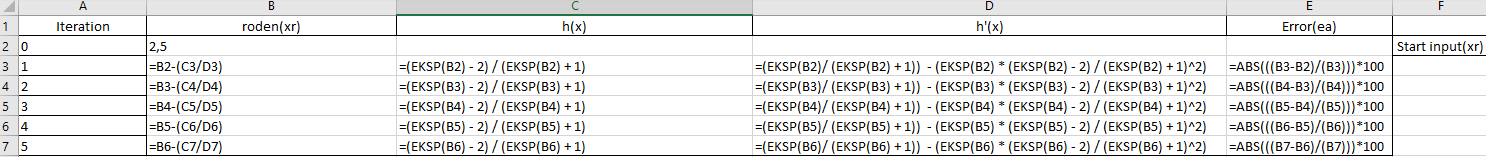

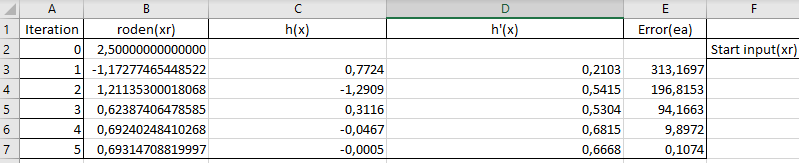

roden er ved 5 iteration $xr = 0,69$ med en fejl på 0,0005 og dete passer med iteration 4 med to decimaler.

I matlab fås

H = matlabFunction(h(x));
H_1 = matlabFunction(h_1(x));
xr = 2.5;
es = 0.0001;
maxit = 5;

[root,ea,iter] = newtraph(H,H_1,xr,es,maxit) 

root = 0.6931

ea = 0.1074

iter = 5

### (1d)

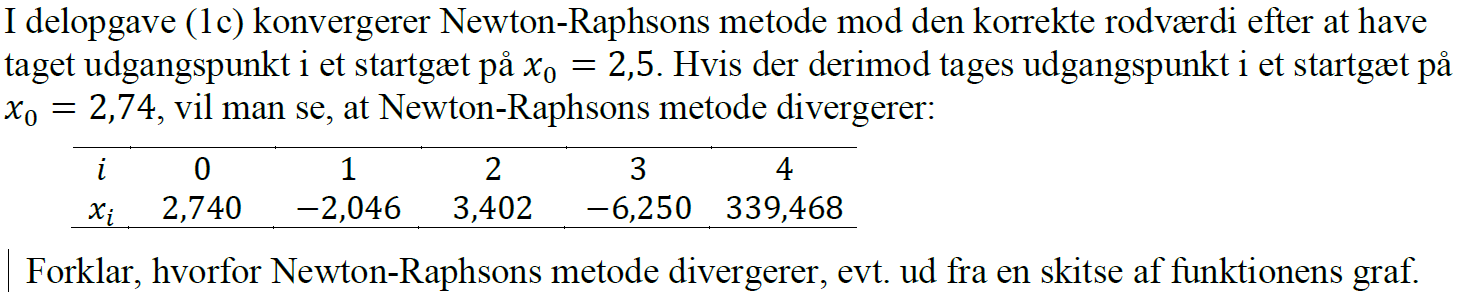


X_test = [2.740, -2.046, 3.402, -6.250] 

X_test =     2.7400   -2.0460    3.4020   -6.2500


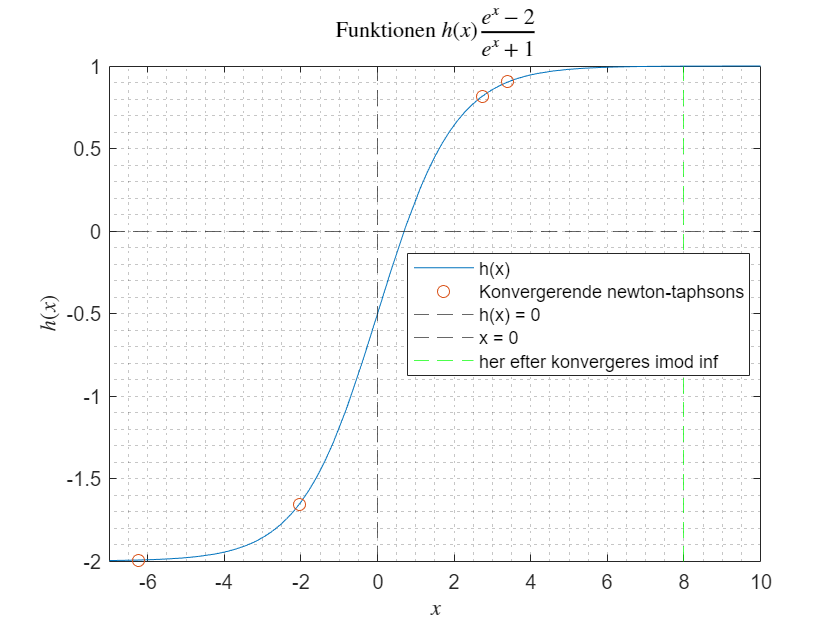


syms x
h(x) = (exp(x) - 2) / (exp(x) + 1);
fplot(h(x), [-7,10], 'DisplayName', 'h(x)')
%der plottes
hold on
plot(X_test, h(X_test), 'o', 'DisplayName', 'Konvergerende newton-taphsons')
yline(0,'--', 'DisplayName', 'h(x) = 0')
xline(0,'--', 'DisplayName', 'x = 0')
xline(8,'g--', 'DisplayName', 'her efter konvergeres imod inf')

% formalier
legend('location', 'best')
title('Funktionen $h(x) \frac{e^x - 2}{e^x + 1}$', 'interpreter', 'latex')
xlabel('$x$', 'interpreter', 'latex')
ylabel('$h(x)$', 'interpreter', 'latex')
grid('minor')
hold off

Vi ser ud fra dataen at der tæstest tættere og tættere på de to områder hvor hældningskoefficenten $g'(x)$ nærmer sig 0. Da vil $\frac{g(x)}{g'(x)}$ konvergere imod uendelig.

Fra løsnings forlaget fortælles

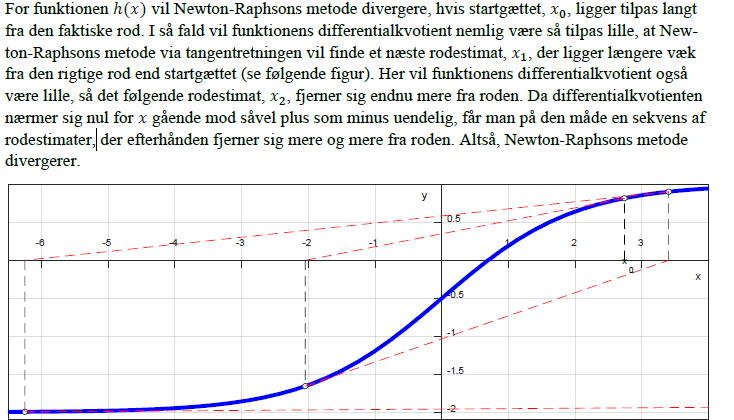

## Opgave 2

clear
u = symunit;

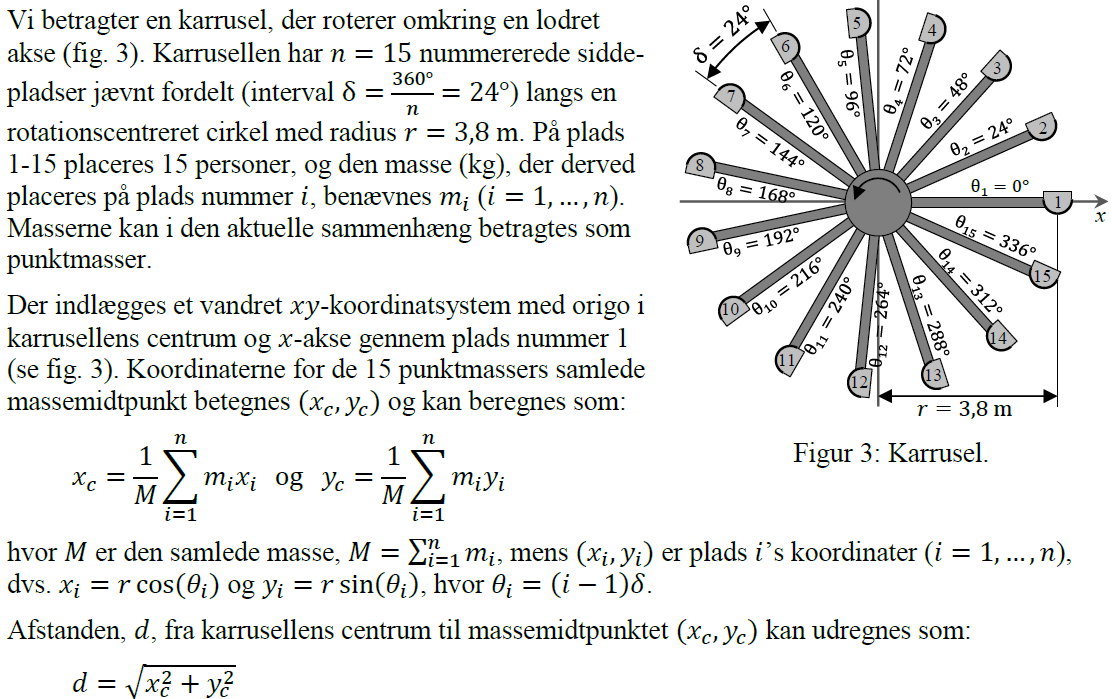

### (2a)

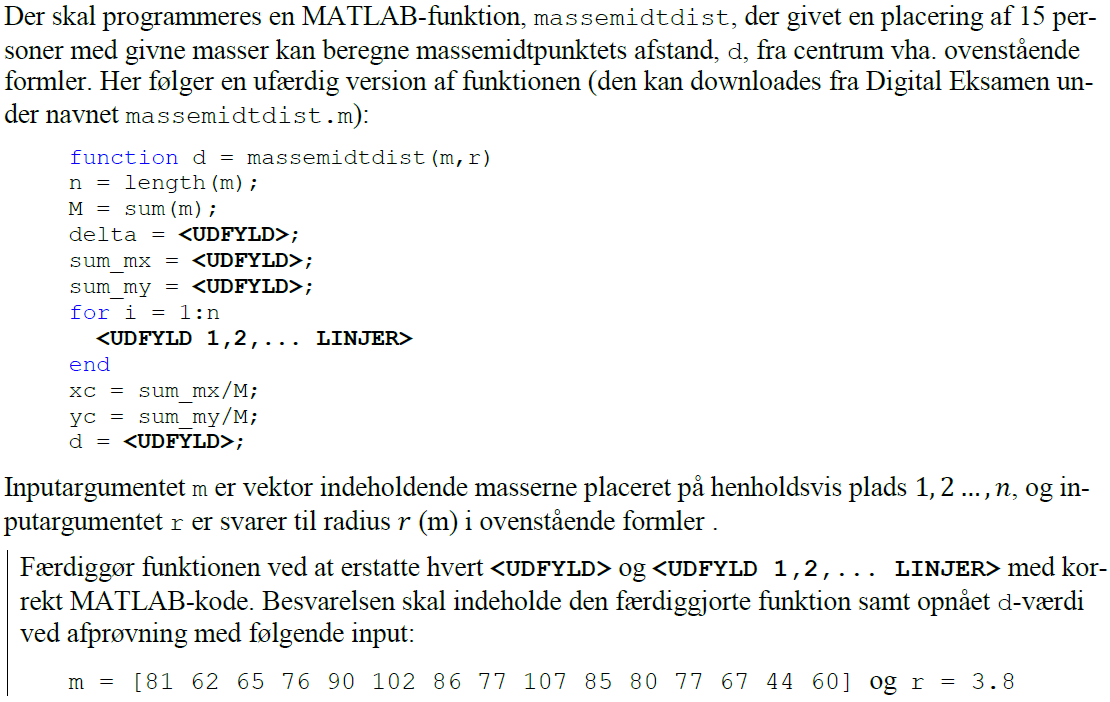

m = [81 62 65 76 90 102 86 77 107 85 80 77 67 44 60]; %vægt for personer
r = 3.8; %radius af kausellen
d_m = massemidtdist(m,r)

d_m = 0.4195

Massemidtpunktet af karocellen er således $d = 0,42$ m fra centrum

### (2b)

clear

m0 = [81 62 65 76 90 102 86 77 107 85 80 77 67 44 60];
r = 3.8;
[m,d] = suboptmindist(m0,r)

m =     60   102    90    62    65    67    85    81    86    80    77    76    77    44   107


d = 6.1241e-04

ans = 0.6124

Således bliver massemidtpunkets placering kun $d=0,61$mm fra centrum.

## Opgave 3

clear

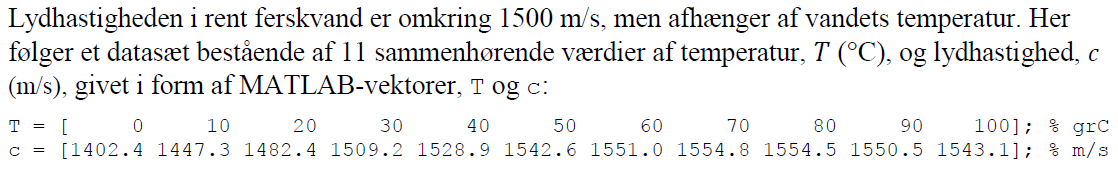

### (3a)

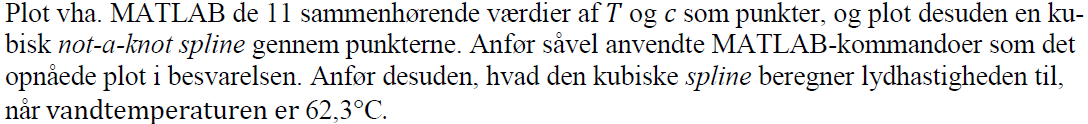

format longg
T = [ 0 10 20 30 40 50 60 70 80 90 100]; % grC
c = [1402.4 1447.3 1482.4 1509.2 1528.9 1542.6 1551.0 1554.8 1554.5 1550.5 1543.1]; % m/s
TT = linspace(min(T), max(T));
c_spline = spline(T,c,TT);
c_spline_62_3 = spline(T,c,62.3)

c_spline_62_3 =           1552.25989359691


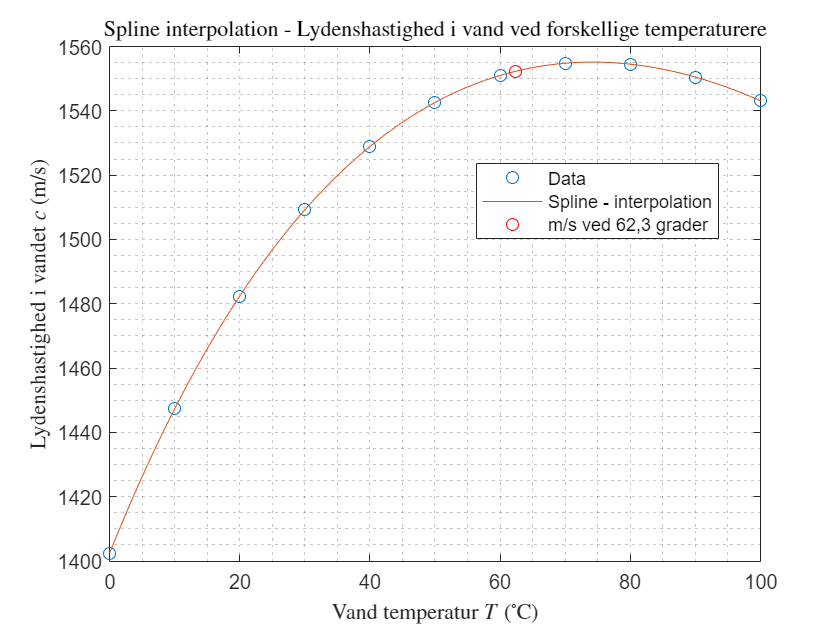


%der plottes
plot(T,c,'o', 'DisplayName', 'Data') %data plottes
hold on
plot(TT,c_spline, 'DisplayName', 'Spline - interpolation') % interpolation med spline plottes

plot(62.3, c_spline_62_3, 'rO', 'DisplayName', 'm/s ved 62,3 grader')
% formalier
legend('location', 'best')
title('Spline interpolation - Lydenshastighed i vand ved forskellige temperaturere', 'interpreter', 'latex')
xlabel('Vand temperatur $T$ ($^{\circ}$C)', 'interpreter', 'latex')
ylabel('Lydenshastighed i vandet $c$ (m/s)', 'interpreter', 'latex')

grid minor
hold off

Lydhastigheden ved $62,3^{\circ} = 1552,3$ m/s

### (3b)

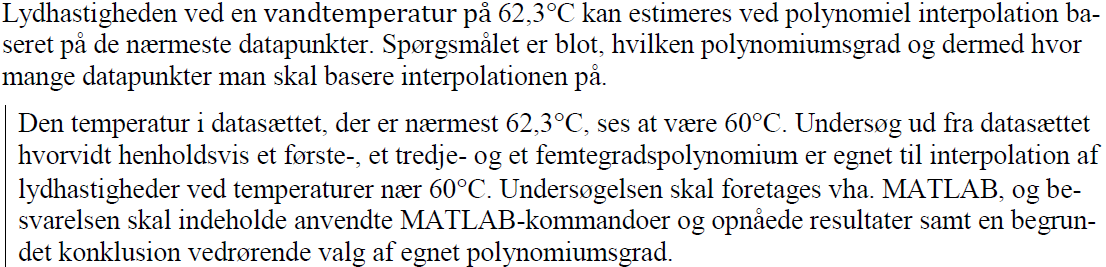

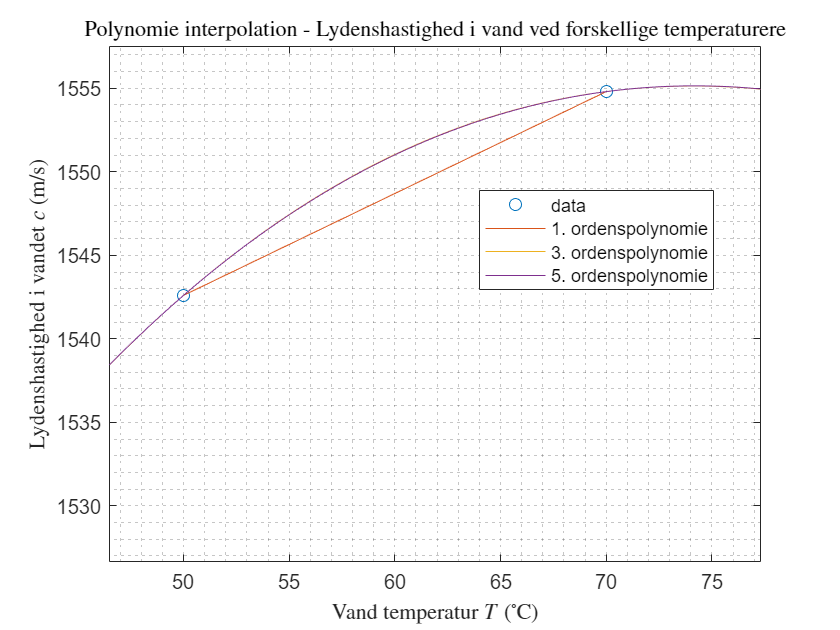

c_select_1 = c([6 8]);
T_select_1 = T([6 8]);
TT_test_1 = linspace(T(6), T(8));
p_fit_1 = polyfit(T_select_1,c_select_1,1);
p_plot_1 = polyval(p_fit_1,TT_test_1); %giver de interpolatede y værdier fra xx værdierne

c_select_3 = c([5 6 8 9]);
T_select_3 = T([5 6 8 9]);
TT_test_3 = linspace(T(5), T(9));
p_fit_3 = polyfit(T_select_3,c_select_3,3);
p_plot_3 = polyval(p_fit_3,TT_test_3); %giver de interpolatede y værdier fra xx værdierne

c_select_5 = c([4 5 6 8 9 10]);
T_select_5 = T([4 5 6 8 9 10]);
TT_test_5 = linspace(T(4), T(10));
p_fit_5 = polyfit(T_select_5,c_select_5,5);
p_plot_5 = polyval(p_fit_5,TT_test_5); %giver de interpolatede y værdier fra xx værdierne

%der plottes
plot(T_select_5,c_select_5, 'o', 'DisplayName', 'data') %data plottes
hold on
plot(TT_test_1,p_plot_1, 'DisplayName', '1. ordenspolynomie') %data plottes

plot(TT_test_3,p_plot_3, 'DisplayName', '3. ordenspolynomie') %data plottes

plot(TT_test_5,p_plot_5, 'DisplayName', '5. ordenspolynomie') %data plottes
% formalier
legend('location', 'best')
title('Polynomie interpolation - Lydenshastighed i vand ved forskellige temperaturere', 'interpreter', 'latex')
xlabel('Vand temperatur $T$ ($^{\circ}$C)', 'interpreter', 'latex')
ylabel('Lydenshastighed i vandet $c$ (m/s)', 'interpreter', 'latex')

xlim([46.5 77.3])
ylim([1526.7 1557.5])
grid minor
hold off

p_plot_1 = polyval(p_fit_1,60)

p_plot_1 =                     1548.7


p_plot_3 = polyval(p_fit_3,60)

p_plot_3 =           1551.03333333333


p_plot_5 = polyval(p_fit_5,60)

p_plot_5 =                   1551.015


p_fit_3

p_fit_3 =       9.99999999999671e-05       -0.0413333333333267          4.47999999999956          1409.43333333334


T_select_3

T_select_3 =     40    50    70    80


Det ses at 3. og 5. ordens polynomierne ligger oveni hinanden og begge giver en go interpolation. **Vi kan dermed nøjes 3. grads polynomiet fundet fra vandtemperaturene 40, 50, 70, 80 **$^{\circ}$**C. Da vi her for et ens resultat med 5. gradspolynomiet inden for 1 decimal, hvilket også er undgangspunktet for vores datasæt.**

### (3c)

Anvend polynomiel interpolation med henholdsvis et første-, et tredje- og et femtegradspolyno-mium til at estimere lydhastigheden ved 62,3C. Benyt et passende antal af de nærmeste datapunk-ter til hver af interpolationsberegningerne. Undersøgelsen skal foretages vha. MATLAB, og be-svarelsen skal indeholde anvendte MATLAB-kommandoer og opnåede resultater samt en kom-mentar om, hvilke(n) af de tre interpolerede værdier, der er mest troværdigt. Inddrag, hvis det fin-des relevant, resultaterne af delopgave (3a) og (3b) i kommentaren.

p_1_62_3 = polyval(p_fit_1,62.3)

p_1_62_3 =                   1550.103


p_3_62_3 = polyval(p_fit_3,62.3)

p_3_62_3 =               1552.2911167


p_5_62_5 = polyval(p_fit_5,62.3)

p_5_62_5 =           1552.27362457869


5. gradspolynomiet med værdien 1552,2607 m/s er umildbart mest præcis da den benytter flere data punkter men 3.grad polynomiet 1552,2632 m/s må vuderes at være næsten lige så god (alt efter formålet) da den først afviger ved 3. decimal. Men da vores data sæt har 1 decimal bør vi også have denne nøjagtighed på vores resultat.

1. gradspolynomiet for en hastighed på 1551,8740 m/s hvilket er mindre præcist.

### (3d)

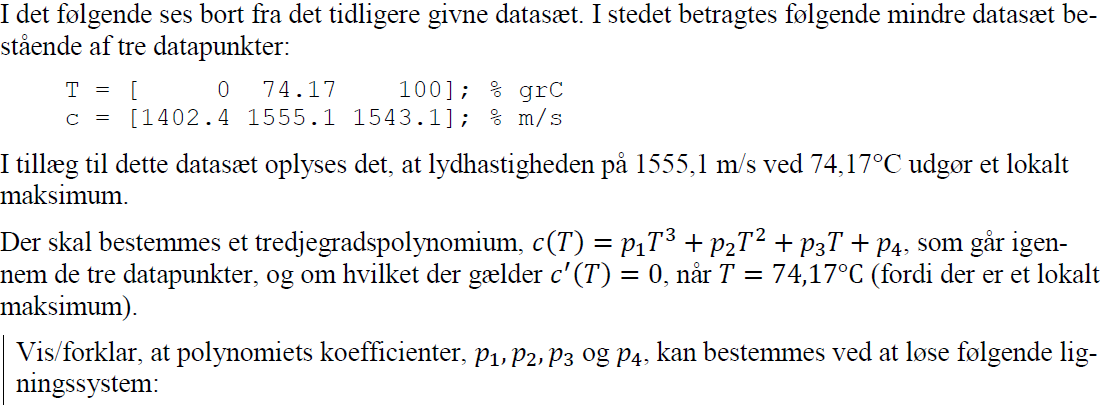

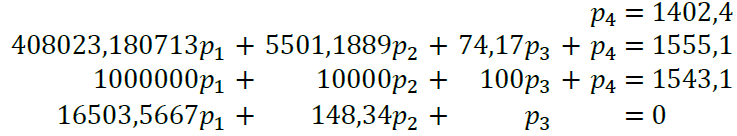

de 3 punkter giver andledning til 3 forskellige ligninger ved at indsætte T værdien.

Det kan det da vi har fire ligning med fire ubekendte vi kan opstille dem som en matrix A og sætte den på RREF form for at aflæse resultaterne. Vi kan også løse systemet med 

Dermed har vi konstanterne $p_1, p_2, p_3, p_4$ til 3. gradspolynomiet

### (3e)

Opstil ligningssystemet fra delopgave (3d) på matrixform og løs det vha. MATLAB. Benyt løsningsværdierne

som grundlag for at plotte polynomiet 𝑐(𝑇) i intervallet 0 til 100C.

A = [0 0 0 1
    408023.180713 5501.1889 74.17 1
    1000000 10000 100 1
    16503.5667 148.34 1 0];

b = [1402.4 1555.1 1543.1 0]';

P = linsolve(A,b)

P =       9.77172543524025e-05
       -0.0422530136826999
          4.65512882474596
                    1402.4


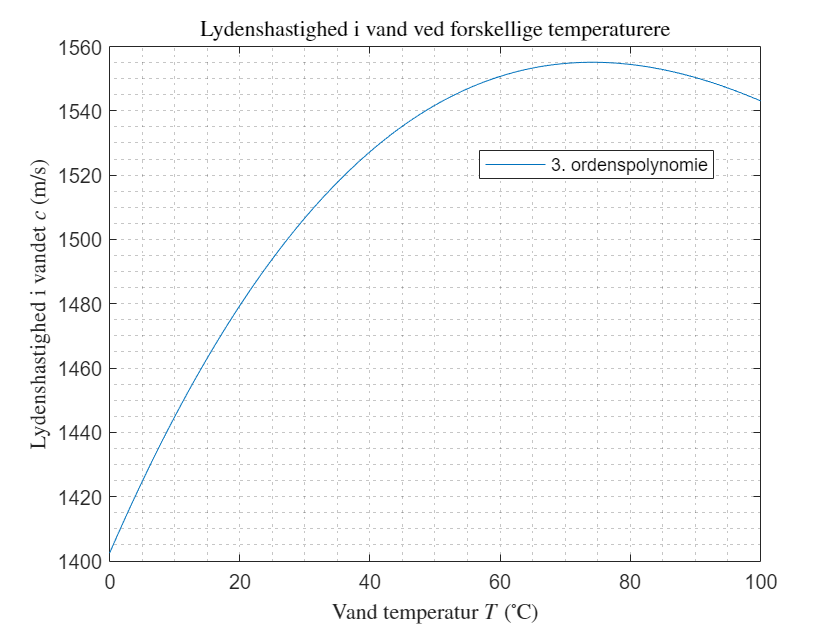

T = linspace(0,100);
% c_T = P(1)*T.^3 + P(2)*T.^2 + P(3)*T + P(4);
c_T = polyval(P,T);

plot(T, c_T, 'DisplayName', '3. ordenspolynomie')
% formalier
legend('location', 'best')
title('Lydenshastighed i vand ved forskellige temperaturere', 'interpreter', 'latex')
xlabel('Vand temperatur $T$ ($^{\circ}$C)', 'interpreter', 'latex')
ylabel('Lydenshastighed i vandet $c$ (m/s)', 'interpreter', 'latex')

grid minor

Vi ser at der er et maximum på plottet omkring $x=74 ^{\circ}C$.

## Opgave 4

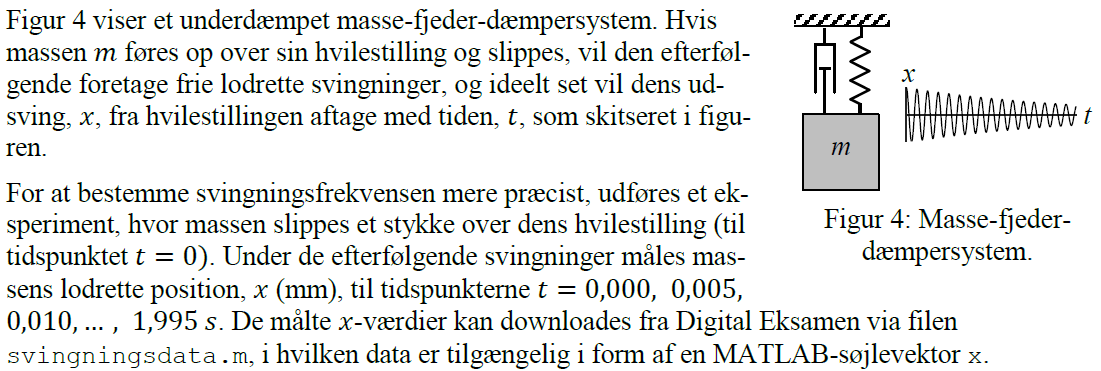

clear

### (4a)

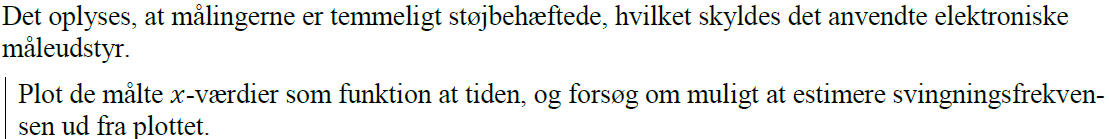

### (4b)

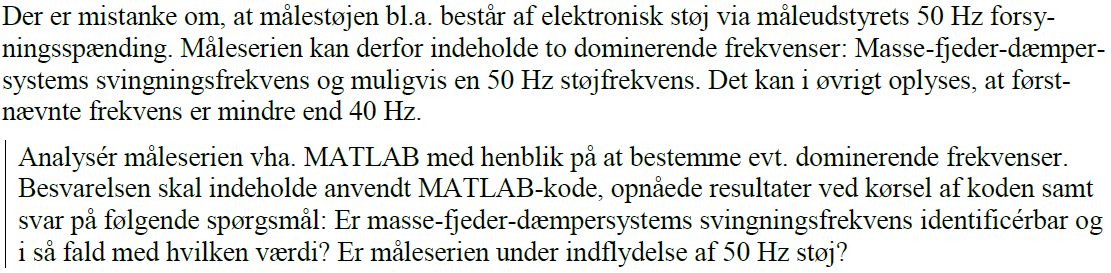

## Plot koder

%der plottes
% plot(t,y,'o', 'DisplayName', 'Data') %data plottes
% hold on
% plot(tt,ned_spl_cub, 'DisplayName', 'interpolation') % interpolation med spline plottes
% 
% % formalier
% legend('location', 'best')
% title('Spline interpolation af data')
% xlabel('$x$ (Dag)', 'interpreter', 'latex')
% ylabel('Akkumulerde nedbor $y$ (mm)', 'interpreter', 'latex')
% grid
% hold off

## Funktioner